% Load the historical data
data = [130 152 263 369 423 416 750 928]';

% Create a time series object
ts = timeseries(data, 2015:2022);

% Extract the data values from the time series object
salesData = ts.Data;

% Plot the historical data
figure;
plot(ts.Time, salesData, '-o')
xlabel('Year')
ylabel('Number of e-bikes sold')
title('Historical E-Bike Sales')
hold on % Hold the plot to append the forecasts

% Create an ARIMA model with seasonal differencing
model = arima('ARLags',1,'D',1,'MALags',1,'Seasonality',0,'Constant',0);

% Estimate the model parameters using the historical data
estmdl = estimate(model, salesData);

 
    ARIMA(1,1,1) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic    PValue 
                ________    _____________    __________    _______

    Constant           0             0             NaN         NaN
    AR{1}              1       0.66261          1.5092     0.13125
    MA{1}       -0.66515        1.5831        -0.42015     0.67438
    Variance       11288         10776          1.0476     0.29482




% Predict the number of e-bikes sold in the next 2 years
future_dates_2years = 2023:2024;
[forecast_2years, ~, forecast_ci_2years] = forecast(estmdl, 2, 'Y0', salesData);
fprintf('Predicted e-bike sales in 2 years: %d\n', round(forecast_2years(end)));

Predicted e-bike sales in 2 years: 1232



% Predict the number of e-bikes sold in the next 5 years
future_dates_5years = 2023:2027;
[forecast_5years, ~, forecast_ci_5years] = forecast(estmdl, 5, 'Y0', salesData);
fprintf('Predicted e-bike sales in 5 years: %d\n', round(forecast_5years(end)));

Predicted e-bike sales in 5 years: 1688


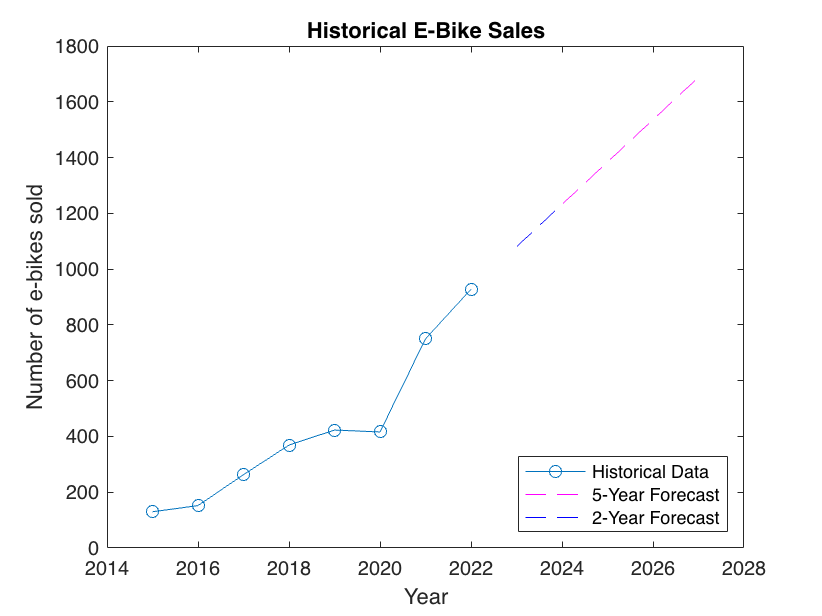


% Plot the forecasted sales
plot(future_dates_5years, forecast_5years, '--', 'Color', 'm')
plot(ts.Time(end)+1:ts.Time(end)+2, forecast_2years, '--', 'Color', 'b')
legend('Historical Data', '5-Year Forecast', '2-Year Forecast', 'Location', 'southeast')
hold off % Release the hold to end the plot